clc;
clear all;

% Thresholds
min_stroke_age = 0;
min_test_age = 0;
min_test_interval = 0.5;

% Get VIPS dataset
project_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction';
beh_csv = readtable(fullfile(project_dir, 'behavior', 'vips_combined_31226.csv'), 'Format', 'auto');
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval, ...
    beh_csv.has_lesion==1],2));    
beh_csv = beh_csv(inc_ind,:);

% Plot behavior
con_motor = summary(categorical(beh_csv.contra_motor));
rlang = summary(categorical(beh_csv.LanguageReception));
elang = summary(categorical(beh_csv.Verbal));
cogbeh = summary(categorical(beh_csv.Cognitive_Behavioral));
left = summary(categorical(beh_csv.Left));
right = summary(categorical(beh_csv.Right));

barh([cogbeh.Counts, rlang.Counts, elang.Counts, left.Counts, right.Counts]', 'stacked');
set(gca, 'YtickLabel', {'Cognitive/Behavior', 'Receptive Language', 'Expressive Language', 'L Sensorimotor', 'R Sensorimotor'});
box off;
xlabel('Number of Patients');
l = legend({'PSOM=0', 'PSOM=0.5', 'PSOM=1', 'PSOM=2'}); l.IconColumnWidth = 5

l =   Legend (PSOM=0, PSOM=0.5, PSOM=1, PSOM=2) with properties:

         String: {'PSOM=0'  'PSOM=0.5'  'PSOM=1'  'PSOM=2'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.747619047619048 0.711671588034116 0.138690476190476 0.182492581602374]
          Units: 'normalized'

  Show all properties


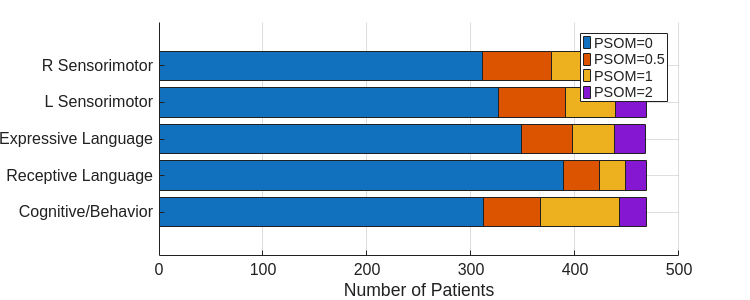

grid on; set(gcf, 'position', [0, 0, 750, 300]); set(gca, 'FontSize', 12); title('');

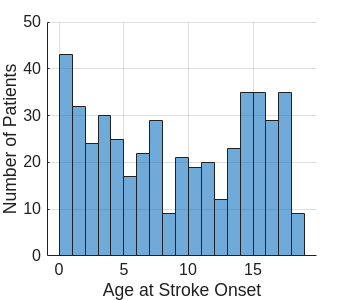

clf;
histogram(beh_csv.stroke_age, 'binWidth', 1);
ylabel('Number of Patients');
xlabel('Age at Stroke Onset');
box off;
grid on; set(gcf, 'position', [0, 0, 350, 300]); set(gca, 'FontSize', 12); title('');

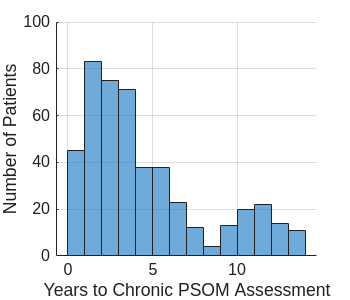

clf;
histogram(beh_csv.yrs2test, 'binWidth', 1);
ylabel('Number of Patients');
xlabel('Years to Chronic PSOM Assessment');
box off;
grid on; set(gcf, 'position', [0, 0, 350, 300]); set(gca, 'FontSize', 12); title('');